% Emmanuelle

% Script to fit calcium dependant fluorescence changes

%load('DataToFit.mat');
%load('Time.mat');

TStart = 1;                     % (in s)
TStartStim = 10;                % (in s)
TEndStim = 20;                  % (in s)
TStop = 59;                     % (in s)
ThresholdLevel = 0.1;           % (between 0 and 1)
Smoothing = 1;                 % number of points used for smoothing data and detecting the max

% crop recording
IdxCrop=(Time >= TStart) & (Time <= TStop);
CropedDataToFit=DataToFit(IdxCrop);
CropedTime=Time(IdxCrop);

% average baseline
IdxBaseline = (Time >= TStart) & (Time <= TStartStim);
Baseline =  DataToFit(IdxBaseline);
CaBaseline = mean(Baseline)

CaBaseline = -7.5774e-04

% Find min of DataToFit
SmoothDataToFit = smooth(CropedDataToFit,Smoothing);
[MinSmoothDataToFit, IdxSmoothMinDataToFit] = min(SmoothDataToFit);
if CropedTime(IdxSmoothMinDataToFit) >= (TEndStim - 2)
TimeMinDataToFit = CropedTime(IdxSmoothMinDataToFit) 
else
disp('the peak of the response was not properly detected')
end

TimeMinDataToFit = 22.3000


% Plot smoothing with data.
figure( 'Name', 'smoothing' );
plot(Time, DataToFit, '.', 'color', 'c') ;
hold on
plot(CropedTime, SmoothDataToFit)
legend( 'data', 'smoothing', 'Location', 'NorthEast', 'Interpreter', 'none' );

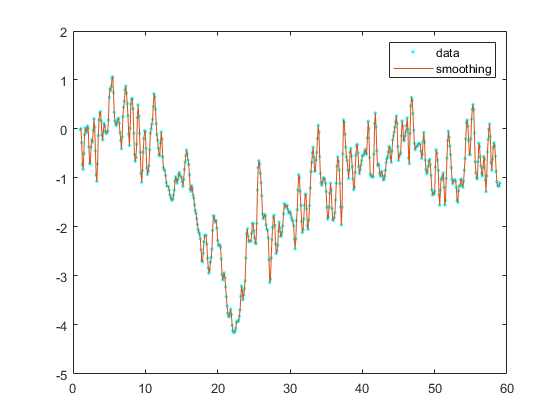

hold off


% Setup data to fit 
IndexFit1 = (CropedTime >= (TimeMinDataToFit - 10)) & (CropedTime <= TimeMinDataToFit);
IndexFit2 = (CropedTime > TimeMinDataToFit) & (CropedTime <= TStop);
[xData1, yData1] = prepareCurveData( CropedTime(IndexFit1), SmoothDataToFit(IndexFit1));
[xData2, yData2] = prepareCurveData( CropedTime(IndexFit2), SmoothDataToFit(IndexFit2));

% Fit  ydata1
% Set up fittype and options.
ft1 = fittype( 'a1*(x-T1)^2 + b1*(x-T1) + c1', 'independent', 'x', 'dependent', 'y' );
opts1 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts1.Display = 'Off';
opts1.Lower = [-Inf -Inf -Inf CaBaseline];
opts1.StartPoint = [10 -1 -1 CaBaseline];
opts1.Upper = [Inf Inf Inf CaBaseline];

% Fit model to data.
[fitresult1, gof1] = fit( xData1, yData1, ft1, opts1 )

fitresult1 =      General model:
     fitresult1(x) = a1*(x-T1)^2 + b1*(x-T1) + c1
     Coefficients (with 95% confidence bounds):
       T1 =       7.329  (-650.6, 665.2)
       a1 =    -0.01756  (-0.02903, -0.006091)
       b1 =    0.001653  (-22.87, 22.88)
       c1 =  -0.0007577  (fixed at bound)

gof1 = struct with fields:
           sse: 19.0963
       rsquare: 0.8128
           dfe: 98
    adjrsquare: 0.8089
          rmse: 0.4414


fitcoeffvals1= coeffvalues(fitresult1);

T1 = fitcoeffvals1(1)

T1 = 7.3292

a1 = fitcoeffvals1(2)

a1 = -0.0176

b1 = fitcoeffvals1(3)

b1 = 0.0017

c1 = fitcoeffvals1(4)

c1 = -7.5774e-04



% Fit  ydata2
% Set up fittype and options.
ft2 = fittype( '-a2*(exp(-(x-b2)/T2)-1)-a3*(exp(-(x-b2)/T3)-1)+c2', 'independent', 'x', 'dependent', 'y' );
opts2 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts2.Display = 'Off';
opts2.Lower = [0 0 0 0 TimeMinDataToFit a1*(TimeMinDataToFit-T1)^2+b1*(TimeMinDataToFit-T1)+c1];
opts2.StartPoint = [1 0.9 20 0.6 TimeMinDataToFit a1*(TimeMinDataToFit-T1)^2+b1*(TimeMinDataToFit-T1)+c1];
opts2.Upper = [Inf Inf Inf Inf TimeMinDataToFit a1*(TimeMinDataToFit-T1)^2+b1*(TimeMinDataToFit-T1)+c1];

[fitresult2, gof2] = fit( xData2, yData2, ft2, opts2 )

fitresult2 =      General model:
     fitresult2(x) = -a2*(exp(-(x-b2)/T2)-1)-a3*(exp(-(x-b2)/T3)-1)+c2
     Coefficients (with 95% confidence bounds):
       T2 =           1  (-0.3291, 2.329)
       T3 =       8.513  (5.419, 11.61)
       a2 =      0.9159  (0.2366, 1.595)
       a3 =       2.516  (1.918, 3.114)
       b2 =        22.3  (fixed at bound)
       c2 =      -3.911  (fixed at bound)

gof2 = struct with fields:
           sse: 97.1684
       rsquare: 0.6633
           dfe: 363
    adjrsquare: 0.6605
          rmse: 0.5174


fitcoeffvals2= coeffvalues(fitresult2);

T2 = fitcoeffvals2(1)

T2 = 1.0002

T3 = fitcoeffvals2(2)

T3 = 8.5134

a2 = fitcoeffvals2(3)

a2 = 0.9159

a3 = fitcoeffvals2(4)

a3 = 2.5161

b2 = fitcoeffvals2(5)

b2 = 22.3000

c2 = fitcoeffvals2(6)

c2 = -3.9112

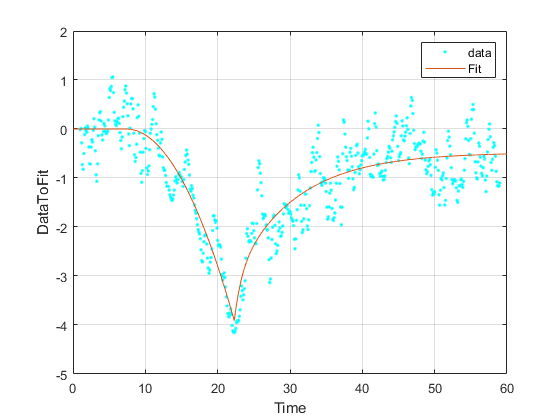

% plot and nomalize

TTime = (0:0.01:60)';
FitTTime = zeros(6001,1);

for icnt = 1:6001
    FitTTime(icnt) = FitCalciumDependantFluoFunction(CaBaseline, TimeMinDataToFit, fitcoeffvals1, fitcoeffvals2, TTime(icnt));
end

% Plot fit with data.
figure( 'Name', 'CalciumDependantFluoFit' );
h = plot(Time, DataToFit, '.', 'color', 'c') ;
hold on
plot(TTime, FitTTime),
legend('data', 'Fit', 'Location', 'NorthEast');
hold off

% Label axes
xlabel( 'Time' );
ylabel( 'DataToFit');
grid on

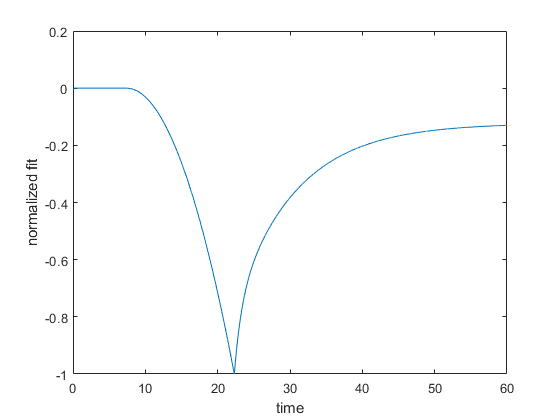

% normalized fit
[MinFit, IdxMin] = min(FitTTime);
NormFit = -(FitTTime - CaBaseline) / (MinFit - CaBaseline);

% plot noorm fit 
figure( 'Name', 'Normalized Fit' );
h2 = plot( TTime, NormFit );
% Label axes
xlabel( 'time');
ylabel( 'normalized fit');

% Threshold calculation
IndexBelowThreshold = (NormFit >= -ThresholdLevel);
IndexBeforeMin = IndexBelowThreshold(1:IdxMin);
TimeBeforeThreshold = TTime(IndexBeforeMin);
[TimeThrehold, IdxTimeThrehold] = max(TimeBeforeThreshold);
TimeThrehold;

IndexBelowThreshold10 = (NormFit >= -0.1);
IndexBeforeMin10 = IndexBelowThreshold10(1:IdxMin);
TimeBeforeThreshold10 = TTime(IndexBeforeMin10);
[TimeThrehold10, IdxTimeThrehold10] = max(TimeBeforeThreshold10);
TimeThrehold10

TimeThrehold10 = 12.0900


IndexBelowThreshold15 = (NormFit >= -0.15);
IndexBeforeMin15 = IndexBelowThreshold15(1:IdxMin);
TimeBeforeThreshold15 = TTime(IndexBeforeMin15);
[TimeThrehold15, IdxTimeThrehold15] = max(TimeBeforeThreshold15);
TimeThrehold15

TimeThrehold15 = 13.1500


IndexBelowThreshold20 = (NormFit >= -0.2);
IndexBeforeMin20 = IndexBelowThreshold20(1:IdxMin);
TimeBeforeThreshold20 = TTime(IndexBeforeMin20);
[TimeThrehold20, IdxTimeThrehold20] = max(TimeBeforeThreshold20);
TimeThrehold20

TimeThrehold20 = 14.0500


TimeThrehold101520 = [TimeThrehold10 ; TimeThrehold15 ; TimeThrehold20];

function y = FitCalciumDependantFluoFunction(CaBaseline, TimeMinDataToFit, fitcoeffvals1, fitcoeffvals2, x)
   if x <= fitcoeffvals1(1)
       y = CaBaseline; 
   elseif x <= TimeMinDataToFit
       y = fitcoeffvals1(2)*(x-fitcoeffvals1(1))^2 + fitcoeffvals1(3)*(x-fitcoeffvals1(1)) + fitcoeffvals1(4); 
   else
       y = -fitcoeffvals2(3)*(exp(-(x-TimeMinDataToFit)/fitcoeffvals2(1))-1) - ...
       fitcoeffvals2(4)*(exp(-(x-TimeMinDataToFit)/fitcoeffvals2(2))-1) + fitcoeffvals2(6);
   end
end